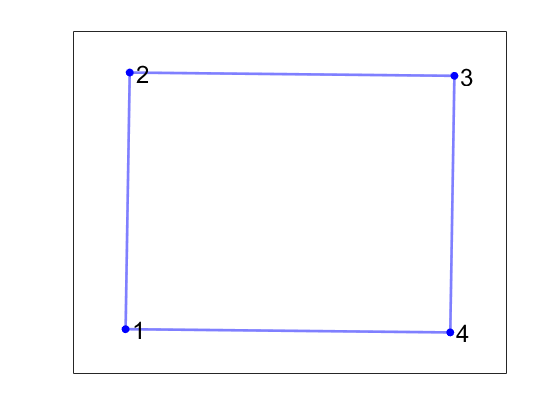

%======== Laplacian =============
n = 4;
figure(1)
A = [0,1,0,1;1,0,1,0;0,1,0,1;1,0,1,0];
G = graph(A);
D = diag(A*ones(n,1));
L = D - A;
plot(G, 'Layout', 'force', 'NodeFontSize', 18, 'MarkerSize', 5, 'LineWidth', 2, 'NodeColor', 'b', 'EdgeColor', 'b')

eig_a=eig(L)

eig_a =     0.0000
    2.0000
    2.0000
    4.0000


disp('Laplacian');

Laplacian


disp(L);

     2    -1     0    -1
    -1     2    -1     0
     0    -1     2    -1
    -1     0    -1     2



disp('Adjacency')

Adjacency


disp(A);

     0     1     0     1
     1     0     1     0
     0     1     0     1
     1     0     1     0



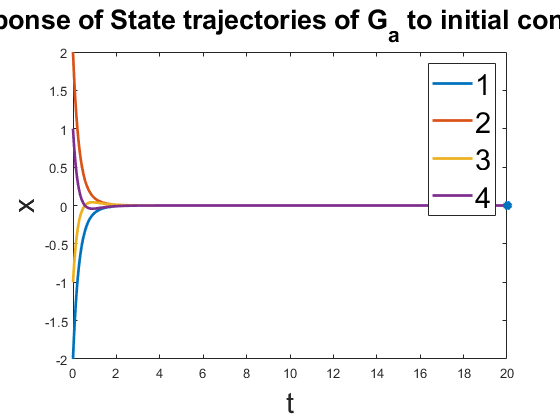



%
x_ini =[ -2; 2;-1; 1; ];
tspan = [0 20];
options = odeset('RelTol',1e-5);

figure(1)
[t, x] = ode45(@ode_a, tspan, x_ini, options);

n1 = length(x);
x = x(1:n1,:);
plot(t,x,'linewidth',2)
hold on
plot(t(end,:),x(end,:),'*','linewidth',4);
% 
xlabel('t', 'FontSize', 22);
ylabel('x', 'FontSize', 22);
legend('1','2','3','4', 'FontSize', 22)
title('Response of State trajectories of G_a to initial condition', 'FontSize', 20)

function x_dot = ode_a(t, x)
 n = 4;
 A = [0,1,0,1;1,0,1,0;0,1,0,1;1,0,1,0];
 G = graph(A);
 D = diag(A*ones(n,1));
 L = D - A;
 x_dot = -L * x;

end